### Metodo de Newton

Realicemos el **punto 6** del taller:

Considere la función:


$$f\left(x\right)=x^2 -4x\;\sin \left(x\right)+{\left(2\;\sin \left(x\right)\right)}^2$$


Hallemos los ceros de la función para todos los reales, y la múltiplicidad de estos:

clear

% Definimos la función como function_handle
f = @(x) x.^2 - 4 * x .* sin(x) + (2 * sin(x)).^2

f = function_handle with value:
    @(x)x.^2-4*x.*sin(x)+(2*sin(x)).^2


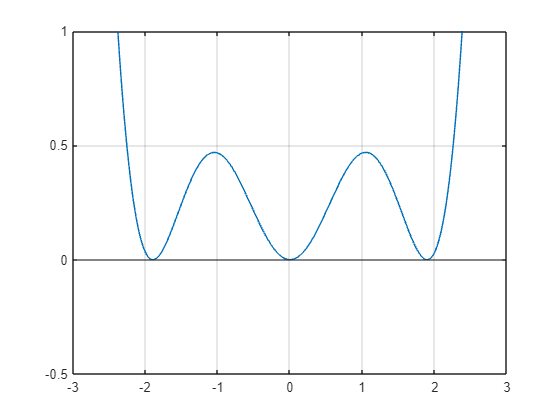

% Creamos un gráfico sencillo de la función
clf("reset")        % Limpiamos la figura
fplot(f, [-3, 3])   % Gráficamos en el intervalo [-3, 3]
ylim([-1/2, 1])     % Limitamos los valores de y para comodidad
yline(0)            % Linea de y = 0
grid on             % Malla en el gráfico

% Definimos el valor de la derivada
df = @(x) 2 * x - 4 * x.*cos(x) - 4*sin(x) + 8 * sin(x).*cos(x)

df = function_handle with value:
    @(x)2*x-4*x.*cos(x)-4*sin(x)+8*sin(x).*cos(x)


% Recordamos los argumentos del método
help newton

  Entrada - f funcion creada con @
          - df funcion derivada creada con @
          - p0 es la aproximacion inicial a cero de  f
 	      - delta es la tolerancia para  p0
 	      - epsilon es la tolerancia para los valores de la funcion  y
 	      - max1 es el numero maximo de iteraciones
  Salida  - p0 es la aproximacion de Newton-Raphson hacia cero
 	      - err es el error estimado para  p0
 	      - k es el numero de iteraciones
 	      - y es el valor de la funcion  f(p0)



% Evaluemos la función
tic     % Inicio de toma de tiempo
% Llamamos la función
[p0, err, k, y] = newton(f, df, 1.5, 1e-15, 1e-30, 100)

p0 = 1.8955

err = 1.0127e-08

k = 25

y = 0

toc     % Fin de toma de tiempo

Elapsed time is 0.013713 seconds.


Consideremos la alternativa de revisar la función simbolica, y como podemos emplearla.

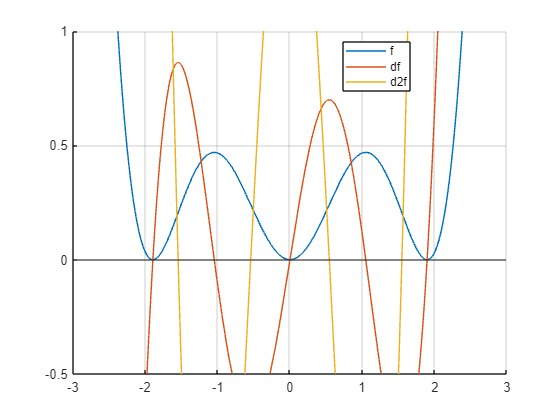

clear

% Definimos la función simbolica
syms f(x)

% Definimos la función simbolica
f(x) = x^2 - 4 * x * sin(x) + (2 * sin(x))^2;

% Hallamos los valores de las primeras 3 derivadas
df(x) = diff(f, x);
d2f(x) = diff(f, x, 2);
d3f(x) = diff(f, x, 3);

% Definimos el cambio de variable de Newton Modificado
h(x) = f(x) / df(x);
dh(x) = diff(h, x);

% Gráficamos el conjunto de funciones
clf('reset')                                % Limpiamos el gráfico
hold on                                     % Reunimos multiples gráficos
fplot(f, [-3, 3], 'DisplayName', 'f')       % Función F
fplot(df, [-3, 3], 'DisplayName', 'df')     % Derivada de F
fplot(d2f, [-3, 3], 'DisplayName', 'd2f')   % Segunda derivada de F
ylim([-1/2, 1])                             % Limitamos los valores de Y
yline(0, 'HandleVisibility', 'off')         % Linea en 0
legend('Location','best')                   % Ubicamos la legenda
grid on                                     % Activamos la malla

f = matlabFunction(f);      % Convertimos a function handle
df = matlabFunction(df);    % Convertimos a function handle
 
% Verificamos el funcionamiento del método
[p0, err, k] = newton(f, df, 1.5, 1e-15, 1e-15, 100)

p0 = 1.8955

err = 2.2131e-08

k = 23

% Definimos la derivada para el método acelerado
% Podemos definirla como otra función
dg = @(x) df(x) / 2;

p0 = 1.8955

err = 1.2773e-04

k = 4

[p0, err, k] = newton(f, dg, 1.5, 1e-15, 1e-15, 100)
% Podemos definirla dentro del método
[p0, err, k] = newton(f, @(x) df(x) / 2, 1.5, 1e-15, 1e-15, 1000)

p0 = 1.8955

err = 1.2773e-04

k = 4

% Argumentos para newton Modificado.
help newtonMod

  Entrada - f funcion creada con @
          - df primera derivada, funcion creada con @
          - d2f segunda derivada, funcion creada con @
          - p0 es la aproximacion inicial a cero de  f
 	      - delta es la tolerancia para  p0
 	      - epsilon es la tolerancia para los valores de la funcion  y
 	      - max1 es el numero maximo de iteraciones
  Salida  - p0 es la aproximacion de Newton-Raphson hacia cero
 	      - err es el error estimado para  p0
 	      - k es el numero de iteraciones
 	      - y es el valor de la funcion  f(p0)



% Convertimos la segunda derivada
d2f = matlabFunction(d2f);

[p0, err, k] = newtonMod(f, df, d2f, 1.5, 1e-15, 1e-15, 100)

p0 = 1.8955

err = 1.5229e-04

k = 4

% Convertimos la función auxiliar
h = matlabFunction(h);
dh = matlabFunction(dh);

% Verificamos los valores de newton y newtonMod
[p0, err, k] = newton(h, dh, 1.5, 1e-15, 1e-15, 100)

p0 = 1.8955

err = 2.1274e-09

k = 6